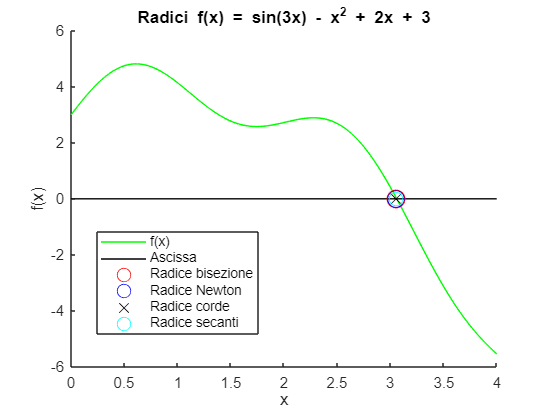

f = @(x) sin(3 .* x) - x .* x + 2 .* x + 3;
fder = @(x) 3 .* cos(3 .* x) - 2 .* x + 2;

[xb, kb] = bisezione(f, 0, 4, 10e-5, 100);
[xn, kn] = newton(f, fder, 1, 10e-5, 100);
[xc, kc] = corde(f, f(4), 4, 10e-5, 100);
[xs, ks] = secanti(f, 0, 2, 10e-5, 100);

x = linspace(0, 4, 200);
figure;
hold on;

xlabel("x");
ylabel("f(x)");
title("Radici f(x) = sin(3x) - x^2 + 2x + 3");
plot(x, f(x), "-g", "DisplayName", "f(x)");
plot(x, zeros(size(x)), "-k", "DisplayName", "Ascissa");

plot(xb, f(xb), "Or", "DisplayName", "Radice bisezione", "MarkerSize", 12);
plot(xn, f(xn), "Ob", "DisplayName", "Radice Newton", "MarkerSize", 11);
plot(xc, f(xc), "xk", "DisplayName", "Radice corde", "MarkerSize", 10);
plot(xs, f(xs), "Oc", "DisplayName", "Radice secanti", "MarkerSize", 9);

legend("Location", "best");

hold off;




function [xs, ks] = secanti(f, x0, x1, tau, kmax)

    % secanti: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0
    %   [x, k] = secanti(f, x0, x1, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.

    % Caso base: x0 è già una soluzione
    if abs(f(x0)) < tau
        xs = x0;
        ks = 0;
        return
    end


    % Inizio algoritmo iterativo da 1 a kmax con passo 1
    for ks = 1 : kmax

        % Controllo che i punti non siano gli stessi
        if x0 == x1
            error("Divisione per 0, modifica x0 e x1");
        end
        
        f0 = f(x0);
        f1 = f(x1);
        
        % Formula secanti
        m = (f1 - f0) / (x1 - x0);
        x_new = x1 - f1 / m;

        % Condizioni di arresto: se la soluzione non è variata
        % significativamente dall'iterazione precedente o se l'immagine
        % risulta abbastanza vicina a 0
        if abs(x_new - x1) < tau * abs(x1) || abs(f(x_new)) < tau
            xs = x_new;
            return;
        end

        % Aggiorno i punti
        x0 = x1;
        x1 = x_new;
    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    xs = x_new;
    warning("Iterazioni massime raggiunte");
   
end

function [xn, kn] = newton(f, fder, x0, tau, kmax)

    % newton: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0
    %   [xn, kn] = newton(f, fder, x0, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.


    % Inizializzo xn
    xn = x0;

    % Se il punto passato è già soluzione lo restituisco
    if(abs(f(x0)) < tau)
        kn = 0;
        return;
    end

    % Inizio algoritmo iterativo da k a kmax
    for kn = 1 : kmax
        
        f1 = fder(x0);

        if(abs(f1) < tau)
            error("La derivata tende a 0: cambia il valore x0");
        end

        % Formula Newton
        xn = x0 - f(x0) / f1;

        % Condizioni di arresto: se la soluzione non è variata
        % significativamente dall'iterazione precedente o se l'immagine
        % risulta abbastanza vicina a 0
        if abs(f(xn)) < tau || abs(xn - x0) < tau * abs(x0)
            return;
        end

        % Aggiornamento variabili
        x0 = xn;

    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    warning("Iterazioni massime raggiunte");

end

function [xc, kc] = corde(f, m, x0, tau, kmax)
    
    % corde: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0 
    %   [xc, kc] = corde(f, m, x0, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.

    % Controllo che il punto iniziale sia già una radice
    if(abs(f(x0)) < tau)
        xc = x0;
        kc = 1;
        return;
    end
    
    % Controllo che m non sia tendente a 0
    if abs(m) < tau
        error("Valore di m troppo vicino a 0");
    end

    % Inizio algoritmo iterativo da k a kmax
    for kc = 1 : kmax

        % Formula corde
        xc = x0 - f(x0) / m;

        % Condizioni di arresto
        if abs(f(xc)) < tau || abs(xc - x0) < tau * abs(x0)
            return;
        end

        % Aggiorno variabile
        x0 = xc;

    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    warning("Iterazioni massime raggiunte");

end

function [xb, kb] = bisezione(f, a, b, tau, kmax)
    
    % bisezione: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0 
    %   [xb, kb] = bisezione(f, a, b, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.


    % Inizializzo la variabile fa con f(a) per non doverla calcolare più
    % volte
    fa = f(a);

    % Controllo che nell'intervallo sia contenuta la radice che cerco
    if(fa * f(b) > 0)
        error("Nessuna radice nell'intervallo [%g, %g]", a, b);
    end


    % Inizio algoritmo iterativo da k a kmax
    for kb = 1 : kmax
       
        % Formula bisezione
        xb = (a + b) / 2;
        
        % Aggiorno l'immagine della x trovata per non doverla calcolare più
        % volte
        fxb = f(xb);

        % Controllo la positività dell'immagine trovata e aggiorno
        % l'intervallo
        if(fa * fxb < 0)
            b = xb;
        else
            a = xb;
            fa = fxb;
        end
        
        % Condizioni di arresto
        if abs(fxb) < tau
            return;
        end

    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    warning("Iterazioni massime raggiunte");

end